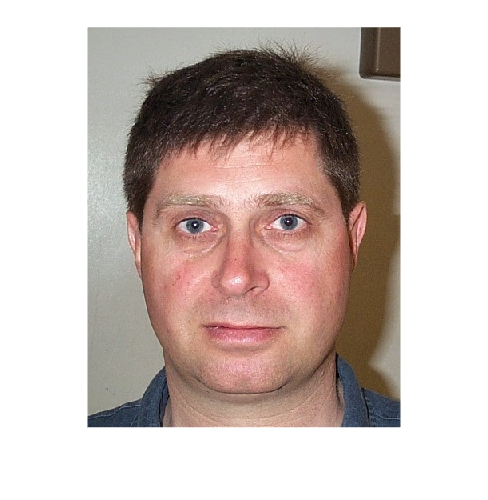

clear 

realId = 1;
im = imread("../Faces/db1_" + realId + ".jpg");
imshow(im)


% Gray world comp start
imR = im(:,:,1);
imG = im(:,:,2);
imB = im(:,:,3);

[m,n,~] = size(im);
R_avg = 1/(m*n)*sum(sum(imR)) 

R_avg = 150.0609

G_avg = 1/(m*n)*sum(sum(imG)) 

G_avg = 122.5832

B_avg = 1/(m*n)*sum(sum(imB))

B_avg = 111.8482

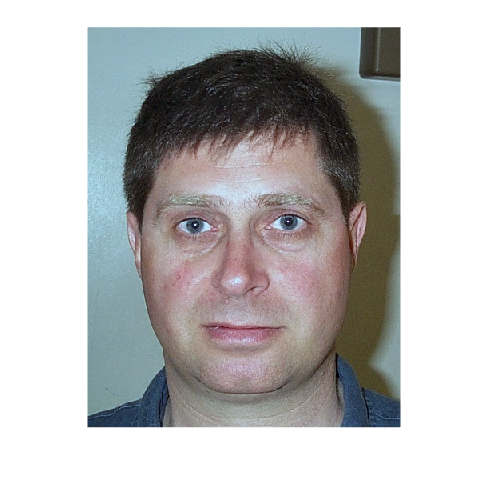


minAvgDiff = 6;

if abs(R_avg - G_avg) > minAvgDiff || abs(R_avg - B_avg) > minAvgDiff || abs(B_avg - G_avg) > minAvgDiff
    alpha = G_avg / R_avg;
    beta = G_avg / B_avg;

    im(:,:,1) = alpha * imR;
    im(:,:,3) = beta  * imB;
end    
imshow(im)

% Gray world comp end
% White patch start

pixelRGBSum = sum(im,3) %

pixelRGBSum =    494   494   488   494   502   497   491   497   485   497   502   502   508   502   497   500   494   497   508   512   497   494   500   500   503   512   498   500   503   495   500   506   502   512   520   512   497   500   505   497   500   502   505   508   508   508   505   502   500   506
   491   491   488   491   499   497   491   494   502   505   502   502   508   505   494   494   502   500   502   502   497   497   505   502   503   509   492   495   500   498   500   498   500   500   500   502   512   515   512   512   505   508   508   508   508   508   508   508   503   509
   502   502   497   499   505   499   491   494   502   500   488   491   505   505   497   494   508   502   502   505   500   502   508   502   508   515   497   497   503   503   506   498   515   509   500   502   515   505   497   509   509   509   508   505   505   508   508   512   512   515
   502   502   499   502   512   505   497   500   500   497   485   485   500   50

brightestPixel = max(pixelRGBSum(:));
[row,col] = find(pixelRGBSum == brightestPixel)

row =    248
   247


col =    135
   136
